# Conducting IQC analysis

The fundamental value of `iqcToolbox` is its ability to leverage integral quadratic constraints (IQCs) to conduct worst-case stability/performance analysis on uncertain and nonlinear systems. This type of analysis is called IQC analysis. After this script, you will gain a superficial understanding of the concepts behind IQC analysis and a concrete understanding of how you can conduct IQC analysis with the commands from `iqcToolbox`.

## Brief theoretical background and why it's important

The central object of analysis in `iqcToolbox` is a linear fractional transformation (LFT) of an uncertain and nonlinear system $(M,\Delta)$, which describes a mapping from disturbance input signals $e$ to output signals $d$ (see equations and block diagram below).


$$\qquad \quad \matrix{ \phi & = & \Delta(\theta) \cr
     \theta & = & M_{11} \phi + M_{12} d \cr
     e & = & M_{21} \phi + M_{22} d}$$


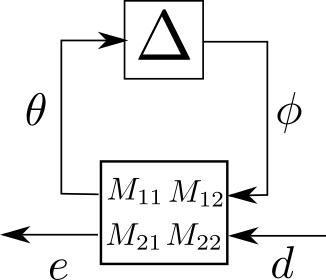

More information on LFTs can be found in the section "Modeling uncertain systems with the Ulft class". 

IQC analysis allows one to characterize the effects of uncertain, troublesome, or complex elements ($\Delta \in \Delta_{\mbox{set}}
$ and $d \in \mathcal{D}$) on the nominal, linear system $M$ and its output $e$, according to a predefined performance metric $\mathcal{P}$. Using the common "$\ell_2$-induced" performance metric with a performance level $\gamma$, conducting IQC analysis results in determining if the LFT $(M, \Delta)$ is robustly stable, and if


$$(1) \qquad||e||_{\ell_2} < \gamma ||d||_{\ell_2}, \mbox{ where } e = (M, \Delta)(d), \ \Delta \in \Delta_\mbox{set}, \ d \in \mathcal{D} \subseteq \ell_2$$


(i.e., the system has a robust $\mathcal{D}$-to-$\ell_2$-induced performance level of $\gamma$) . IQC analysis represents worst-case analysis, meaning that it produces (if feasible) the tightest upper bound $\gamma$ on how much any admissible disturbance may "affect" the output of any admissible element in the set of uncertain systems.

Characterizing the performance metric $\mathcal{P}$, the set of admissible uncertainties/nonlinearites $\Delta_\mbox{set}$, and the set of admissible disturbances $\mathcal{D}$ is done with so-called IQC multipliers $\Pi_P$, $\Pi_\Delta$, and $\Pi_D$, which are linear, self-adjoint operators that (in this toolbox) have state-space expresssions. To generalize (1), we consider a generic performance metric characterized by the performance multiplier $\Pi_P$ and say that $(M, \Delta)$ has a robust $\mathcal{D}$-$\mathcal{P}$ performance if $(M,\Delta)$ is robustly stable and if

 
$$(2) \qquad \langle \left[\matrix{e \cr d}\right], \Pi_P \left[\matrix{e \cr d}\right]\rangle < 0\mbox{ where } e = (M, \Delta)(d), \ \Delta \in \Delta_\mbox{set}, \ d \in \mathcal{D} \subseteq \ell_2$$


with $\langle \cdot, \cdot \rangle$denoting the inner-product over $\ell_2$. Note, equation (1) can be recovered from equation (2) by defining $\Pi_P = \left[\matrix{I & 0 \cr 0 & -\gamma^2 I}\right]$.

IQC multipliers $\Pi_P$, $\Pi_\Delta$, $\Pi_D$ are composed of basis functions and decision variables that must satisfy constraints according to the properties of $\mathcal{P}$, $\Delta_\mbox{set}$, and $\mathcal{D}$.  IQC analysis amounts to defining the appropriate constraints on $\Pi_P$, $\Pi_\Delta$, $\Pi_D$, and using $M$, $\Pi_P$, $\Pi_\Delta$, and $\Pi_D$ to formulate and solve a semidefinite program.  If a feasible solution exists, then (2) holds.  If not, then we can make no robustness conclusions.

Importantly, the default structure and complexity of each class of IQC multipliers is already defined in `iqcToolbox`. However, users can provide simpler or richer expressions of each utilized IQC multiplier when conducting IQC analysis. This capability helps users find a balance between the expressiveness of the constraints and the tractability of the semidefinite program.

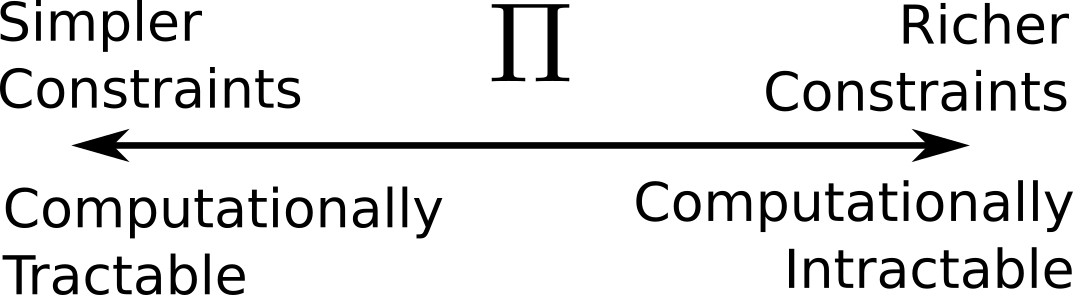

Finding the right balance oftentimes matters, because semidefinite programs tend to produce worse results on the border of "computationally intractable" problems.  Hence, users may find that simpler constraints not only reduce solution times, but sometimes may also reduce the conservatism of the results themselves.

## Basic IQC analysis

Consider the example first introduced in the "Getting started" documentation:


$$G_\delta: \quad \quad \matrix{ 
x(k+1) & = & \left[\matrix{ 0 & 3/4 + \delta \cr 3/4 - \delta & 0}\right] & x(k)& + & \left[\matrix{1 \cr 0}\right] & u(k) \cr
y(k) & = & \left[\matrix{1\quad& 0}\right] & x(k)}$$



$$\mbox{ where } \delta \in [-1/2, 1/2]$$


dims = 1;
lower_bound = -1/2;
upper_bound = 1/2;
% a 1x1 Static, Linear, Time-Invariant (SLTI) uncertainty with the given bounds
del = DeltaSlti('del', dims, lower_bound, upper_bound)  
a_del = [0, 3/4 + del; 3/4 - del, 0];   % the uncertain A-matrix 
b = [1; 0];
c = [1, 0];
d = 0;
timestep = -1;   % An unspecified timestep
g_del = toLft(a_del, b, c, d, timestep) % the uncertain system defined with the uncertain A-matrix

As discussed in the "Modeling uncertain systems with the Ulft class" documentation, a `Ulft` object expresses the nominal portion of the system (`a`, `b`, `c`, `d`), the uncertainties (`delta`), the performance (`performance`), and the disturbances (`disturbance`), which is enough information to directly call `iqcAnalysis`.

result = iqcAnalysis(g_del)

Calling `iqcAnalysis` with this single argument will likely constitute a large majority of a user's invocation of the function. However, `iqcAnalysis` has numerous additional arguments that can be included to provide users more flexibility.

## Additional input arguments to `iqcAnalysis`

`iqcAnalysis` may be called with up to four additional key/value pair arguments:

options = AnalysisOptions();                                             % To be defined later
m_del(2) = MultiplierSlti(g_del.delta.deltas{2});                        % To be defined later
m_perf = MultiplierL2Induced(g_del.performance.performances{1},...
                             size(g_del, 1),...
                             size(g_del, 2));                            % To be defined later
m_dis = MultiplierL2(g_del.disturbance.disturbances{1}, size(g_del, 2)); % To be defined later
result = iqcAnalysis(g_del,...
                     'analysis_options', options,...
                     'multipliers_delta', m_del,...
                     'multipliers_performance', m_perf,...
                     'multipliers_disturbance', m_dis)         

The next sections describe each input argument in detail.

### `analysis_options`

This input argument allows users to express options in the analysis routine that affect the IQC analysis problem universally (rather  than particularly on a single uncertainty, disturbance, or performance). The input must be an `AnalysisOptions` object, which (as of v0.9.0) has 3 different types of parameters: semidefinite solver parameters, parameters describing the initial conditions of $(M, \Delta)$, and an exponential IQC parameter. We will discuss the first two types here; a discussion on the exponential IQC parameter is found in-depth in the "Exponential IQCs" documentation. 

#### Semidefinite solver parameters

`lmi_shift`, `solver`, `verbose`, and `debug` are four parameters that are particular to how the semidefinite program is parsed. Their default values are the input arguments below:

options = AnalysisOptions('lmi_shift', 1e-8, 'solver', 'SDPT3', 'verbose', true, 'debug', false);

The `lmi_shift` parameter prescribes how strict inequalities are enforced in the semidefinite constraints:


$$X\succ 0 \Rightarrow X\succeq (\texttt{lmi\_shift} )I$$


In some cases, `iqcAnalysis` may provide a result which is invalid (i.e., `result.valid == 0 && result.performance == inf`), even though the solver reports that an optimal solution was found. This is usually because semidefinite solvers sometimes produce a solution that barely violates constraints. Users can address this issue by specifying `lmi_shift` to be slightly larger, such that the obtained solution still remains positive or negative definite. However, increasing `lmi_shift` too much may lead to overly conservative or infeasible problems. Unfortunately, this issue arises differently in different machines, so users may need to adapt `lmi_shift` on different platforms and problems.

The `solver` parameter may be any solver installed on your machine (SPDT3 is open-source and the only solver installed with `iqcToolbox`). The remaining parameters are self-explanatory.

#### Uncertain initial conditions

IQC analysis can also incorporate the effect of uncertain initial conditions on the system's worst-case performance.  If $(M,\Delta)$ has an internal state, and the initial state resides in an ellipse centered about zero:


$$x_M(0) \in E(\Xi) = \{x \in \mathbb{R}^n | x^T \Xi x \leq 0\}$$


then IQC analysis can measure the robust $({E(\Xi),\mathcal{D})\mbox{-to-}\ell_2$-induced performance level $(\gamma, \lambda)$, which guarantees that:


$$(3) \qquad \langle \left[\matrix{e \cr d}\right], \Pi_P \left[\matrix{e \cr d}\right]\rangle < \lambda^2\mbox{ where } e = (M^{ic}, \Delta)(d), \ \Delta \in \Delta_\mbox{set}, \ d \in \mathcal{D} \subseteq \ell_2, x_M(0) \in E(\Xi)$$


If using the typical $\ell_2$-induced performance metric, (3) becomes


$$(4) \qquad ||e||^2_{\ell_2} < \gamma^2 ||d||^2_{\ell_2} + \lambda^2\mbox{ where } e = (M^{ic}, \Delta)(d), \ \Delta \in \Delta_\mbox{set}, \ d \in \mathcal{D} \subseteq \ell_2, x_M(0) \in E(\Xi)$$


The ellipse of uncertain initial conditions is specified with parameters in the `analysis_options` variable.  For example, consider the previous system with initial conditions allowed to exist in the unit ball:


$$G^{ic}_\delta: \quad \quad \matrix{ 
x(k+1) & = & \left[\matrix{ 0 & 3/4 + \delta \cr 3/4 - \delta & 0}\right] & x(k)& + & \left[\matrix{1 \cr 0}\right] & u(k), \qquad ||x(0)|| \leq 1 \cr
y(k) & = & \left[\matrix{1\quad& 0}\right] & x(k)}$$



$$\mbox{ where } \delta \in [-1/2, 1/2]$$


Analysis of this system is accomplished by specifying this ellipse in  `analysis_options` when calling `iqcAnalysis`:

e_mat = eye(2); % Ellipse specified as {x in R^n | x' * e_mat * x <= 1}
uncertain_states = [true, true];
options = AnalysisOptions('init_cond_ellipse', e_mat,'init_cond_states', uncertain_states);
result_ic = iqcAnalysis(g_del, 'analysis_options', options)

The key/value pair `{'init_cond_ellipse', e_mat}` specifies $\Xi$ in the ellipse description $E(\Xi) = \{x \in \mathbb{R}^n | x^T \Xi x \leq 0\}$

The key/value pair `{'init_cond_states', uncertain_states}` indicates which states are uncertain. In the previous case, both are.  However, consider the scenario where only one state is uncertain:


$$G^{ic}_\delta: \quad \quad \matrix{ 
x(k+1) & = & \left[\matrix{ 0 & 3/4 + \delta \cr 3/4 - \delta & 0}\right] & x(k)& + & \left[\matrix{1 \cr 0}\right] & u(k), \qquad -1 \leq x_1(0)  \leq 1 \cr
y(k) & = & \left[\matrix{1\quad& 0}\right] & x(k)}$$



$$\mbox{ where } \delta \in [-1/2, 1/2]$$


This would require `e_mat` and `uncertain_states` to change: 

e_mat = 1;
uncertain_states = [true, false]
options = AnalysisOptions('init_cond_ellipse', e_mat,'init_cond_states', uncertain_states);
result_ic = iqcAnalysis(g_del, 'analysis_options', options)

If, instead, we wanted to specify $-3 \leq x_2(0) \leq 3$:

e_mat = 1 / 3 ^ 2;
uncertain_states = [false, true]
options = AnalysisOptions('init_cond_ellipse', e_mat,'init_cond_states', uncertain_states);
result_ic = iqcAnalysis(g_del, 'analysis_options', options)

We can see that incorporating uncertain initial conditions increases the `performance` level:

[result.performance result_ic.performance] % [x0 == 0, x0 in ellipse]

and produces a new variable `state_amplification`, which represents $\lambda$ in Eqns (3) and (4):

[result.state_amplification, result_ic.state_amplification] % [x0 == 0, x0 in ellipse]

Because we have introduced uncertainty in the initial conditions, IQC analysis is no longer optimizing just one variable (`result_ic.performance`, or in other words, $\gamma$), but two variables `(result_ic.state_amplification`, or in other words, $\lambda$). This vector optimization problem must be scalarized, and the weighting on the state amplification objective is expressed with the input option `scale_state_obj`

% optimize(result.performance + options.scale_state_obj * result.state_amplification)

If we set this weighting to zero, IQC analysis will return a very large `state_amplification` value:

options = AnalysisOptions('scale_state_obj', 0,...
                          'init_cond_ellipse', e_mat,...
                          'init_cond_states', uncertain_states);
result_ic = iqcAnalysis(g_del, 'analysis_options', options);
result_ic.state_amplification

If instead `scale_state_obj` were high, we would get a much smaller `state_amplification` value:

options = AnalysisOptions('scale_state_obj', 1e4,...
                          'init_cond_ellipse', e_mat,...
                          'init_cond_states', uncertain_states);
result_ic = iqcAnalysis(g_del, 'analysis_options', options);
result_ic.state_amplification

The last option that is associated with uncertain initial conditions is `p0`. This is largely for debugging purposes, and allows users to specify an explicit solution matrix which, among other conditions, must satisfy $P_0 \leq \Xi$.

### Specifying IQC multipliers

In addition to `analysis_options`, users may specify the properties of specific multipliers for specific uncertainties, disturbances, and performances.  This enables a tailored balancing of conservativeness and computational complexity.  These multipliers are broken three different arrays: `multipliers_delta`, `multipliers_disturbance`, and `multipliers_performance`. If a multiplier is not specified, the default parameters for that multiplier are used instead.

The remainder of this section will use the following `analysis_options`

options = AnalysisOptions('lmi_shift', 1e-7);

### `multipliers_delta`

This array of multipliers pertains to each `Delta` object in a `Ulft`. Consider the system:


$$G_\delta: \quad \quad \matrix{ 
x(k+1) & = & \left[\matrix{ \delta_1(k) & 3/4 + \delta_2 \cr 3/4 - \delta_2 & 0}\right] & x(k)& + & \left[\matrix{1 \cr 0}\right] & u(k) \cr
y(k) & = & \left[\matrix{1\quad& 0}\right] & x(k)}$$



$$\mbox{ where } \delta_1(k) \in [-1/2,  \ 1/2] \mbox{ and } \delta_2 \in [-1/2, \ 1/2]$$


del1 = DeltaSltv('del1', dims, -3/8, 3/8);
del2 = DeltaSlti('del2', dims, -1/2, 1/2);
a_dels = [del1,       3/4 + del2;
          3/4 - del2,          0];
g_dels = toLft(a_dels, b, c, d, timestep)

g_dels = A [ 0,  1]-eventually periodic LFT with   1 outputs,   1 inputs,   2 states, and
  2 uncertainties forming a   3 x   3 uncertainty block
********************************************************************************
**********************************   DELTAS   **********************************
     DelayZ  is a   2 x 2       delay operator 
              with an undefined timestep 
     del1    is a   1 x 1     SLTV uncertainty 
              within the bounds: [-0.4, 0.4] 
     del2    is a   2 x 2     SLTI uncertainty 
              within the bounds: [-0.5, 0.5] 

we could specify an explicit multiplier for `del2`, the `DeltaSlti` object:

mult_slti = MultiplierSlti(g_dels.delta.deltas{3})

mult_slti =   MultiplierSlti with properties:

          basis_length: 2
           basis_poles: -0.5000
        basis_function: [2×1 tf]
     basis_realization: [2×1 ss]
     block_realization: [4×2 ss]
           upper_bound: 0.5000
             dim_outin: 2
    constraint_q11_kyp: 1
    constraint_q12_kyp: 0
                  name: 'del2'
                filter: [1×1 struct]
         decision_vars: {[4×4 sdpvar]  [4×4 sdpvar]  [2×2 sdpvar]}
           constraints: [1×1 lmi]
                  quad: [1×1 struct]
        horizon_period: [0 1]
              discrete: 1
           exponential: []
            filter_lft: [8 Ulft]


mults_del(3) = mult_slti

mults_del =   1×3 heterogeneous MultiplierDelta (MultiplierDeltaDefault, MultiplierSlti) array with properties:

    name
    filter
    decision_vars
    constraints
    quad
    horizon_period
    discrete
    exponential
    filter_lft


results = iqcAnalysis(g_dels, 'multipliers_delta', mults_del, 'analysis_options', options)


 num. of constraints =  3
 dim. of sdp    var  =  4,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.0e+01|2.0e+01|4.0e+02|-4.000000e-05  0.000000e+00| 0:0:00| chol  1  1 
 1|0.903|1.000|2.0e+00|1.0e-01|3.8e+01|-5.732062e-06  0.000000e+00| 0:0:00| chol  1  1 
 2|0.988|1.000|2.4e-02|1.0e-02|4.6e-01|-6.878618e-08  0.000000e+00| 0:0:00| chol  1  1 
 3|0.989|1.000|2.6e-04|5.8e-03|5.0e-03|-7.586097e-10  0.000000e+00| 0:0:00| chol  1  1 
 4|0.989|1.000|2.9e-06|1.5e-04|5.5e-05|-8.351610e-12  0.000000e+00| 0:0:00| chol  1  1 
 5|0.989|1.000|3.2e-08|5.8e-07|6.1e-07|-9.178447e-14  0.000000e+00| 0:

results = struct with fields:
                performance: Inf
        state_amplification: NaN
                    ellipse: []
        multiplier_combined: [1×1 MultiplierPerformanceCombined]
          multipliers_delta: [1×3 MultiplierDelta]
    multipliers_disturbance: [1×1 MultiplierL2]
    multipliers_performance: [1×1 MultiplierL2Induced]
              kyp_variables: {[6×6 sdpvar]  [6×6 sdpvar]}
                exponential: 1
                      debug: [1×1 struct]
                      valid: 0


The previous lines of code are actually no different than simply calling `iqcAnalysis(g_dels)`, because `mult_slti` was generated for `del2` with all the default parameters. However, we could specify a richer set of multipliers describing `del2` in the optimization problem:

mult_slti = MultiplierSlti(g_dels.delta.deltas{3}, 'basis_length', 3)

mult_slti =   MultiplierSlti with properties:

          basis_length: 3
           basis_poles: -0.5000
        basis_function: [3×1 tf]
     basis_realization: [3×1 ss]
     block_realization: [6×2 ss]
           upper_bound: 0.5000
             dim_outin: 2
    constraint_q11_kyp: 1
    constraint_q12_kyp: 0
                  name: 'del2'
                filter: [1×1 struct]
         decision_vars: {[6×6 sdpvar]  [6×6 sdpvar]  [4×4 sdpvar]}
           constraints: [1×1 lmi]
                  quad: [1×1 struct]
        horizon_period: [0 1]
              discrete: 1
           exponential: []
            filter_lft: [12 Ulft]


mults_del(3) = mult_slti;
results = iqcAnalysis(g_dels, 'multipliers_delta', mults_del, 'analysis_options', options)


 num. of constraints =  3
 dim. of sdp    var  =  4,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.0e+01|2.0e+01|4.0e+02|-4.000000e-05  0.000000e+00| 0:0:00| chol  1  1 
 1|0.903|1.000|2.0e+00|1.0e-01|3.8e+01|-5.732062e-06  0.000000e+00| 0:0:00| chol  1  1 
 2|0.988|1.000|2.4e-02|1.0e-02|4.6e-01|-6.878618e-08  0.000000e+00| 0:0:00| chol  1  1 
 3|0.989|1.000|2.6e-04|5.8e-03|5.0e-03|-7.586097e-10  0.000000e+00| 0:0:00| chol  1  1 
 4|0.989|1.000|2.9e-06|1.5e-04|5.5e-05|-8.351610e-12  0.000000e+00| 0:0:00| chol  1  1 
 5|0.989|1.000|3.2e-08|5.8e-07|6.1e-07|-9.178447e-14  0.000000e+00| 0:

results = struct with fields:
                performance: Inf
        state_amplification: NaN
                    ellipse: []
        multiplier_combined: [1×1 MultiplierPerformanceCombined]
          multipliers_delta: [1×3 MultiplierDelta]
    multipliers_disturbance: [1×1 MultiplierL2]
    multipliers_performance: [1×1 MultiplierL2Induced]
              kyp_variables: {[10×10 sdpvar]  [10×10 sdpvar]}
                exponential: 1
                      debug: [1×1 struct]
                      valid: 0


Multipliers are specified for each `Delta` object by ordering the array of `MultiplierDelta` objects in correspondence with the array of `Delta` objects in a specific `Ulft`. For the previous example, we see:

mults_del'(:)
g_del.delta.deltas{:}

It's important to ensure that the specified multiplier matches the order of the deltas in the `Ulft` object. For example, `g_del.delta.deltas{2}` is the `DeltaSltv` object `del1:`

g_del.delta.deltas{2}

and mults_del(2) is the `MultiplierDeltaDefault`, meaning it is defined by `g_del.delta.deltas{2}` and the default parameters for it's corresponding `MultiplierDelta` class:

mults_del(2)

In this example, `mults_del(1)` would pertain to the `g_del.delta.deltas{1}`, which is the state-evolution operator `DeltaDelayZ`:

g_del.delta.deltas{1}

Having a multiplier for `DeltaDelayZ` may be somewhat confusing to the user, since state-evolution operators (`DeltaDelayZ `in discrete-time, and `DeltaIntegrator` in continuous-time) are not characterized with multipliers in IQC theory. This design choice for the toolbox was made to maintain a one-to-one correspondence between the user-provided `multipliers_delta` array and the array of `Delta` objects in an LFT (`mults_del(1)` pertains to `g_del.delta.deltas{1}`, `mults_del(2)` pertains to `g_del.delta.deltas{2}`, and so on). The `iqcAnalysis` routine recognizes and ignores multiplier specifications pertaining to state-evolution operators.